cur_cam = [-0.1599 -0.5817 0.2291 3.1416 -0.0000 -3.1416]; % for test

cur_cam =    -0.1599   -0.5817    0.2291    3.1416         0   -3.1416


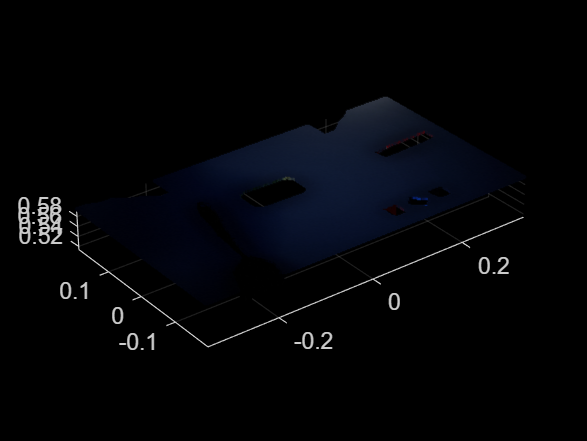

photo_pose_id = 1;
valid_range = [-0.4, 0.4, -0.3, -0.1;
               -0.4, 0.01, -0.3, 0.3;
               -0.24, 0.32, -0.3, 0.15;
               -0.085, 0.085, -0.127, 0.127;
               -0.4, 0.4, -0.3, 0.3;
               -0.4, 0.4, -0.3, 0.3;
               -0.4, 0.4, -0.3, 0.3;]; % [x_min x_max y_min y_max]
minPoints = 50;
rgb = imread(sprintf('dataset/world1/rgb%d.png', photo_pose_id)); 
depth = imread(sprintf('dataset/world1/depth%d.png', photo_pose_id));
depth_data = double(depth) / 255;
imgWidth = 1280;
imgHeight = 720;
resized_size = [64, 64];
% [fx, fy, cx, cy]
fx = 1109.0;
fy = 1109.0;
cx = 640.0;
cy = 360.0;
K = [fx  0  cx;
      0  fy cy;
      0  0  1];
validIdx = depth_data > 0.2 & depth_data < 0.9;
[rows, cols] = size(depth_data);
[u, v] = meshgrid(1:cols, 1:rows);
X = (u - cx) .* depth_data / fx;
Y = (v - cy) .* depth_data / fy;
Z = depth_data;
points3D = [X(validIdx), Y(validIdx), Z(validIdx)];
colors = reshape(rgb, [], 3); 
colors = colors(validIdx, :); 
ptCloud = pointCloud(points3D, 'Color', colors);
pcshow(ptCloud);

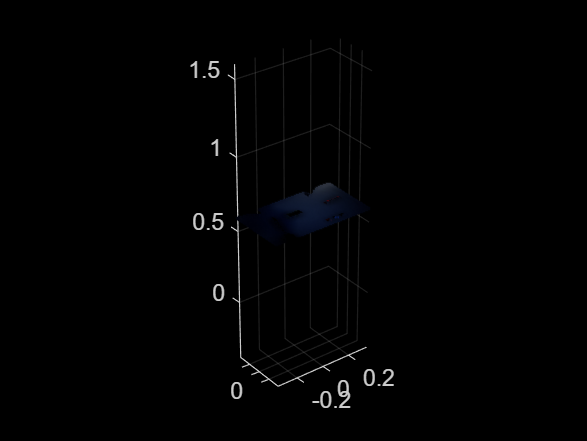


% extract ground
[~, inliers] = pcfitplane(ptCloud, 0.001);
groundCloud = select(ptCloud, inliers);
outliers = setdiff(1:ptCloud.Count, inliers);
foreCloud = select(ptCloud, outliers);
pcshow(groundCloud);

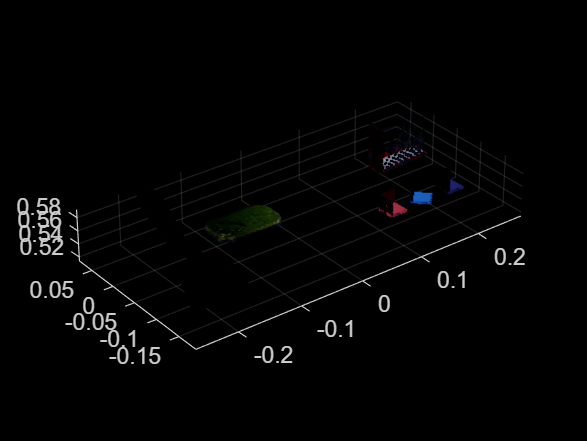

pcshow(foreCloud);


% filter invalid area
range = valid_range(photo_pose_id, :); 
validPoints = foreCloud.Location(:,1) >= range(1) & ...
              foreCloud.Location(:,1) <= range(2) & ...
              foreCloud.Location(:,2) >= range(3) & ...
              foreCloud.Location(:,2) <= range(4);
validCloud = select(foreCloud, validPoints);
pcshow(validCloud);

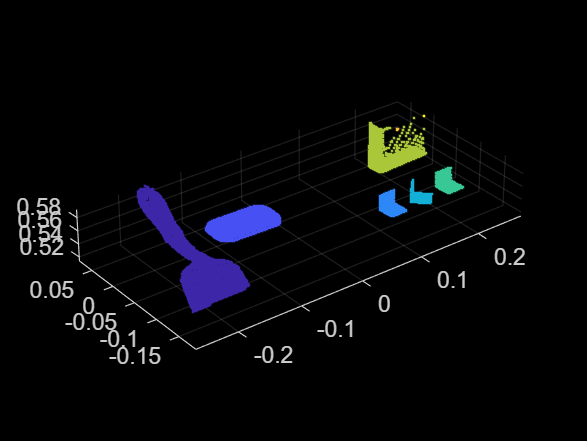


% labels = dbscan(objectCloud.Location, 0.01, 10);
[labels, numClusters] = pcsegdist(validCloud, 0.01);
pcshow(validCloud.Location, labels);


clusterClouds = cell(1, numClusters);
for i = 1:numClusters
    clusterIndices = (labels == i);
    subCloud = select(validCloud, clusterIndices);
    clusterClouds{i} = subCloud;
end

clusterCenters = zeros(numClusters, 2);
clusterZ = zeros(numClusters, 1);
pointCounts = zeros(numClusters, 1);
for i = 1:numClusters
    clusterPoints = clusterClouds{i}.Location;
    clusterCenters(i, :) = mean(clusterPoints(:,1:2), 1);
    clusterZ(i, :) = mean(clusterPoints(:, 3), 1);
    pointCounts(i) = clusterClouds{i}.Count;
end

% filter min points noisy
validClusters = (pointCounts >= minPoints);
objectClouds = clusterClouds(validClusters); 
objectCenters = clusterCenters(validClusters, :);
objectZ = clusterZ(validClusters, :);                           
numObjects = numel(objectClouds);

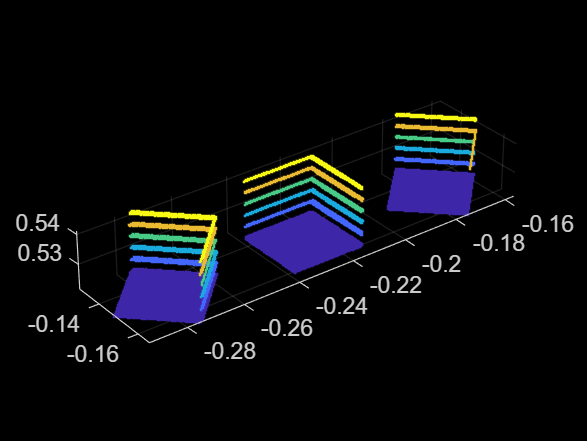

%% generate grasp pose
k = 1;

% % select by approaching img center
% norms = vecnorm(objectCenters, 2, 2);
% [sortedNorms, sortIdx] = sort(norms);
% selectedIdx = sortIdx(k);
% targetCloud = objectClouds{selectedIdx}; 

% select by Z
[sortedZ, sortIdx] = sort(objectZ);
selectedIdx = sortIdx(k);
targetCloud = objectClouds{selectedIdx}; 

pcshow(targetCloud.Location, 'r');
hold on;
for i = 1:numObjects
    pcshow(objectClouds{i}.Location)
end
hold off;

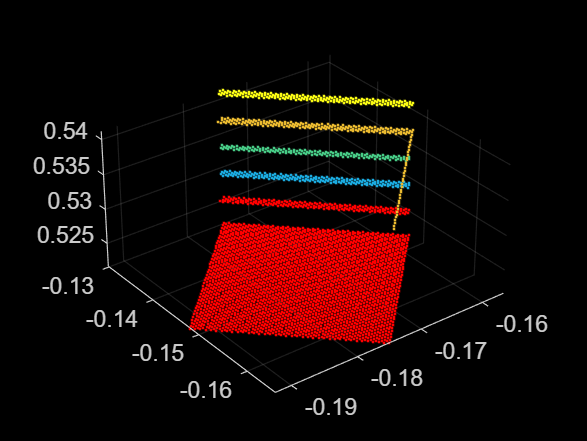


[model, inliers] = pcfitplane(targetCloud, 0.005, [0 0 1]);
planeCloud = select(targetCloud, inliers);
pcshow(targetCloud.Location);
hold on;
pcshow(planeCloud.Location, 'r');
hold off;


[coeff, ~] = pca(planeCloud.Location);
second_axis = coeff(:,2)'; 
center = mean(planeCloud.Location, 1);

v_proj = [second_axis(1), second_axis(2), 0];
theta = acos(dot(v_proj, [1,0,0])/norm(v_proj));
theta = mod(theta + pi, 2*pi) - pi; % [-pi, pi]
if theta > pi/2 % [-pi/2, pi/2]
    theta = theta - pi;
elseif theta < -pi/2
    theta = theta + pi;
end
grasp_pose = [cur_cam(1) - center(1) + 0.05, ...
              cur_cam(2) + center(2), ...
              cur_cam(3) - center(3), ...
              cur_cam(4) + theta, ...
              cur_cam(5), ...
              cur_cam(6)];


%% generate data
bgColor = [11, 20, 43];
for i = 1:numObjects
    points3D = objectClouds{i}.Location;
    colors = objectClouds{i}.Color;    
    u = (points3D(:,1) .* fx) ./ points3D(:,3) + cx;
    v = (points3D(:,2) .* fy) ./ points3D(:,3) + cy;
    uv = round([u, v]);

    validIndices = uv(:,1) >= 1 & uv(:,1) <= size(rgb,2) & ...
                   uv(:,2) >= 1 & uv(:,2) <= size(rgb,1);
    uvValid = uv(validIndices, :);

    mask = false(size(rgb,1), size(rgb,2));
    linearIndices = sub2ind(size(mask), uvValid(:,2), uvValid(:,1));
    mask(linearIndices) = true;

    xMin = max(min(uvValid(:,1)), 1);
    xMax = min(max(uvValid(:,1)), size(rgb,2));
    yMin = max(min(uvValid(:,2)), 1);
    yMax = min(max(uvValid(:,2)), size(rgb,1));
    bboxWidth = xMax - xMin + 1;
    bboxHeight = yMax - yMin + 1;

    maskedImg = rgb;
    for c = 1:3
        channel = maskedImg(:,:,c);
        channel(~mask) = bgColor(c); 
        maskedImg(:,:,c) = channel;
    end

    cropped = imcrop(maskedImg, [xMin, yMin, bboxWidth-1, bboxHeight-1]);

    squareSize = max(bboxWidth, bboxHeight);
    squareImg = repmat(reshape(uint8(bgColor),1,1,3), squareSize, squareSize, 1);

    xOffset = floor((squareSize - bboxWidth)/2);
    yOffset = floor((squareSize - bboxHeight)/2);

    squareImg(yOffset+1:yOffset+bboxHeight,...
             xOffset+1:xOffset+bboxWidth, :) = cropped;

    resizedImg = imresize(squareImg, resized_size, 'bilinear');
    imwrite(resizedImg, sprintf('Logs/cluster_%d.png',i));
end